# Vibration of a single degree of freedom systems (SDOF), mass_spring_damper:

## Introduction:

Goal is producing "Amplification ratio-Frequency ratio" graph of an SDOF mass_spring_damper.

This graph shows the relation between [displacement under driving force or max amplitude of steady state solution OVER deflection under static force] and [driving frequency over natural frequency].

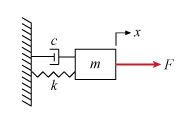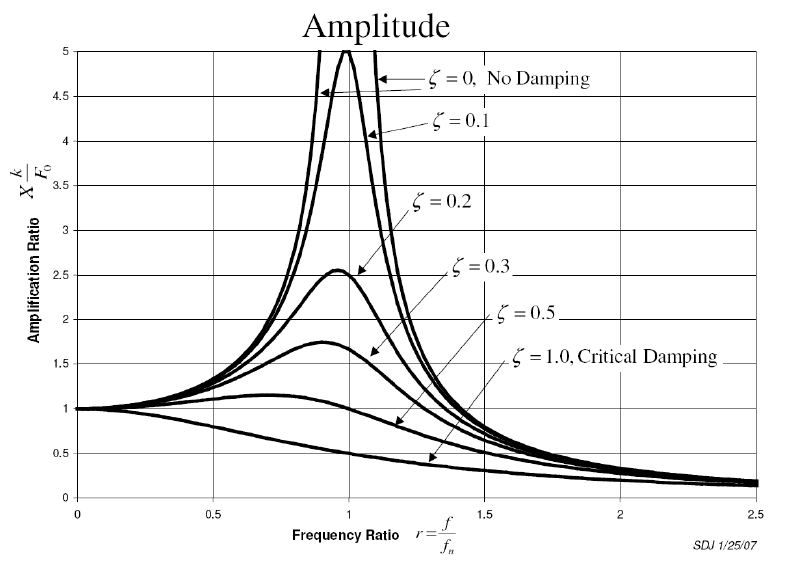

## Theory:

For a mass-spring-damper system, the equation of motion is normally derived using force method, energy method, or Lagrange equation.

The equation of motion for a Spring-mass-damper system under harmonic excitation force is: 

The response to any external excitation is called forced response, if the excitation is harmonic the respond is called harmonic or steady state respond and if it is not periodic the respond is transient respond. The steady state respond can be written as follow:

OR

Note: The second solution may cause sign errors.

In all the equation up to this point $\omega$ is force frequency. The natural frequency of the system is defined as .

Here the frequency ratio is defined as: 

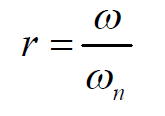

The deflection under static force $F_0$is:

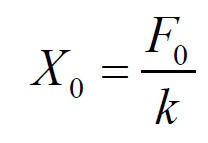

Finally, the magnification factor or amplitude ratio is defined as:

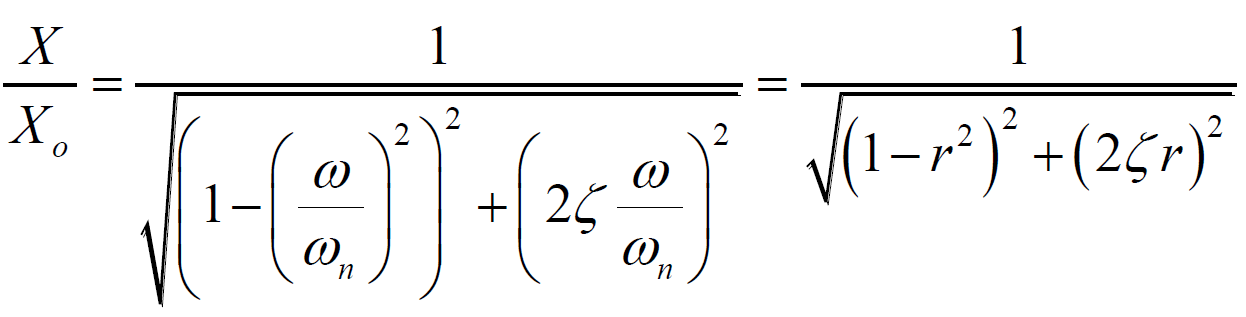

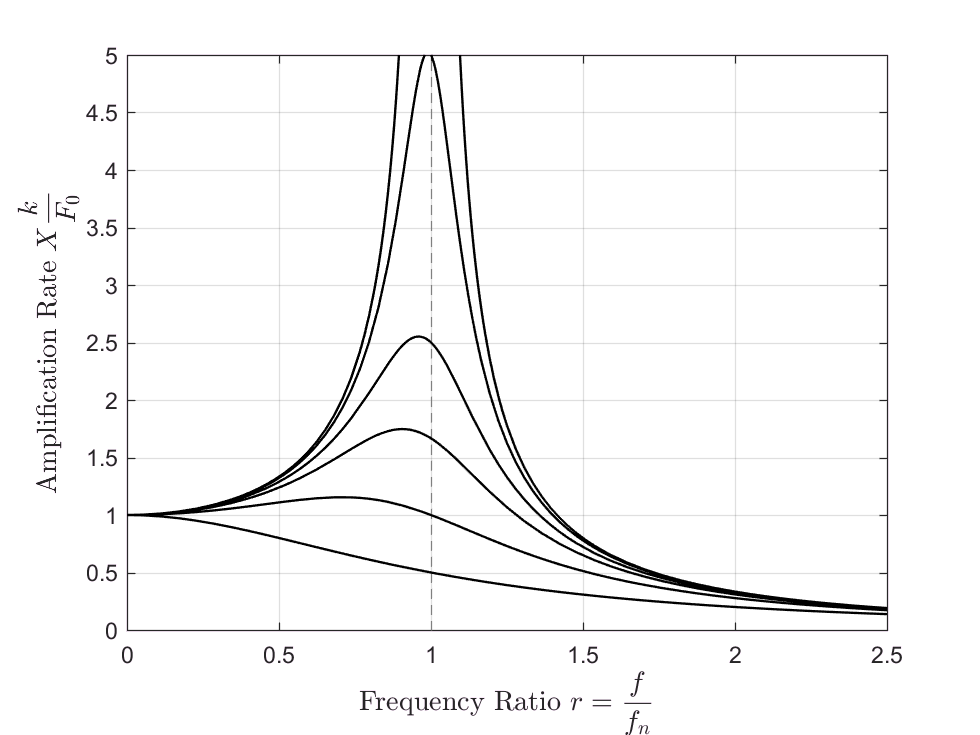


clear; close all; clc
syms omegaN omega t zeta real;
i=0;
for zeta=[0 0.1 0.2 0.3 0.5 1]
    i=i+1;
M(i)=1/sqrt((1-(t*omega/omegaN).^2).^2+(2*(t*omega/omegaN)*zeta).^2);
end
GG=subs(M, [omega,omegaN], [1,1]);
MyPlot(GG)